# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Práctica 3. Segmentación de Imágenes**

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autoras: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

El **objetivo** principal de esta práctica es familiarizarse con las técnicas de segmentación de imágenes:

- Desde niveles más sencillos que requieren intervención por parte del usuario (segmentación supervisada) para fijar umbrales, establecer los parámetros de los modelos etc., hasta niveles más complejos que trabajan de forma automática o semi-automática (segmentación no supervisada).

- A partir de técnicas basadas en el histograma, técnicas de agrupamiento (clustering) en regiones y técnicas de bordes. 

- Basadas en métodos lineales y no lineales de clasificación de cada píxel de la imagen en la región que le corresponda.

 A lo largo de la práctica se solicitará que: 

- Se aplique, de forma práctica algunas de las técnicas de segmentación estudiadas, verificando la problemática y limitaciones de las mismas.

- Se compare unas técnicas de segmentación con otras, analizando el porcentaje de acierto de las mismas.

- Se distinga la segmentación supervisada frente a la no supervisada.

- Se diferencie la segmentación basada en técnicas lineales frente a no lineales.

 Al igual que en la práctica anterior, acabadas las actividades propuestas, se entregará una **memoria, realizada sobre este mismo fichero,** sobre las mismas que incluya, para cada ejercicio:  

- Imagen original/Imagen procesada/dato solicitado.

- Imágenes intermedias (si existen y son de interés).

- Código.

- Explicación del código y justificación/conclusiones sobre el resultado obtenido.

Se valorará positivamente la ampliación de la memoria con las explicaciones que considere oportunas, pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), descripción de problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. Realice cada ejercicio como sección independiente, visualizando los resultados conjuntamente con subplot cuando sea conveniente, e insertando instrucciones para cerrar ventanas (*close all*), eliminar las variables del *workspace *(*clear all*) y pausar (*pause*), donde considere necesario. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

clc;
clear all;
close all;

**Ejercicios propuestos:**

**1.** Segmentación del histograma supervisada lineal:

- Genere una imagen con objetos con varios niveles de gris diferente (al menos 4). 

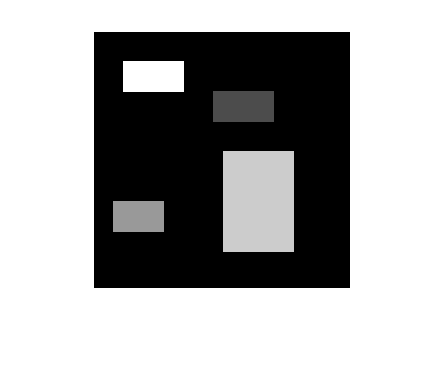

% creamos una imagen en negro
I = zeros(256,256); 
% creamos cuatro rectángulos
I(60:90, 120:180) = 0.3; 
I(170:200, 20:70) = 0.6; 
I(120:220, 130:200) = 0.8; 
I(30:60, 30:90) = 1; 

figure;
imshow(I);

- Añada ruido gaussiano de media **m = 0** y varianza **var_gauss = 0,005.**

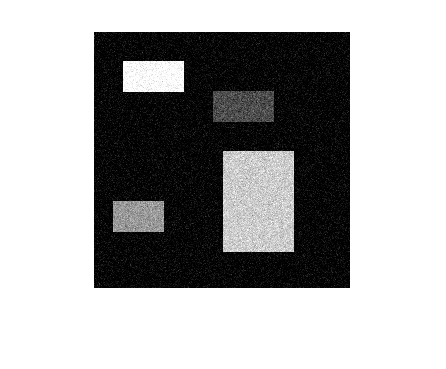

I_gaussian = imnoise(I, 'gaussian', 0, 0.005);

figure;
imshow(I_gaussian);

- Fíltrelo con un filtro de wiener2 (imagen I).

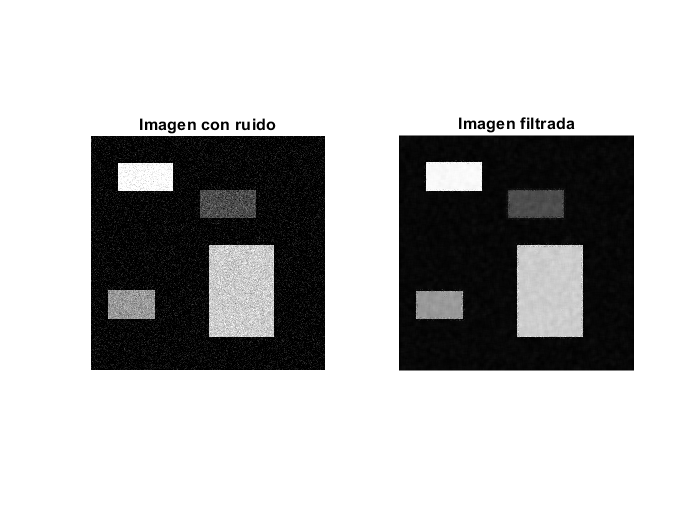

I_wiener = wiener2(I_gaussian, [5 5]);

figure;
subplot(1,2,1); imshow(I_gaussian); title("Imagen con ruido");
subplot(1,2,2); imshow(I_wiener);   title("Imagen filtrada");

- Calcule y muestre el histograma de la imagen I con ruido y filtrada.

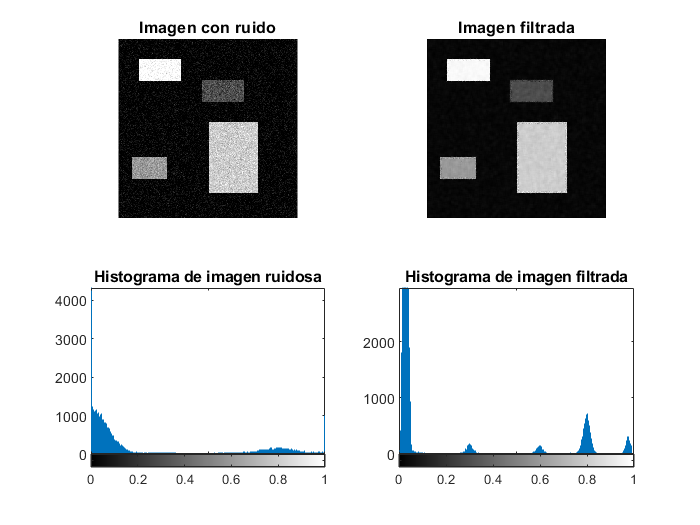

figure;
subplot(2,2,1); imshow(I_gaussian); title("Imagen con ruido");
subplot(2,2,2); imshow(I_wiener);   title("Imagen filtrada");
subplot(2,2,3); imhist(I_gaussian); title("Histograma de imagen ruidosa")
subplot(2,2,4); imhist(I_wiener);   title("Histograma de imagen filtrada")

- A la vista del histograma, utilice tantos umbrales como sea necesario y de los valores adecuados para segmentar uno de los objetos de la imagen (de nivel intermedio de gris). Puede introducirlos con un control deslizante (*numeric slider*) o pidiéndolos en el prompt de Matlab con la instrucción: umbral = input('Introduce valor del umbral X a la vista de la figura del histograma '). 

- Obtenga la imagen correspondiente al objeto segmentado en el apartado anterior.

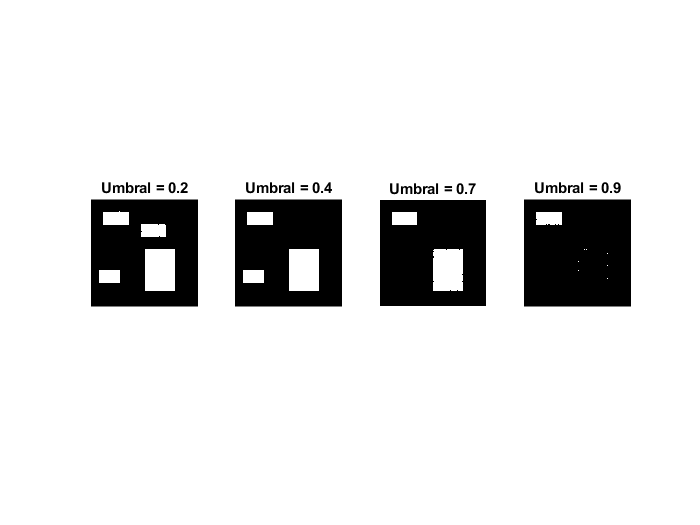

% usando umbrales independientes
um1 = (I_wiener >= 0.2);
um2 = (I_wiener >= 0.4);
um3 = (I_wiener >= 0.7);
um4 = (I_wiener >= 0.9);

figure;
subplot(1,4,1); imshow(um1); title("Umbral = 0.2");
subplot(1,4,2); imshow(um2); title("Umbral = 0.4");
subplot(1,4,3); imshow(um3); title("Umbral = 0.7");
subplot(1,4,4); imshow(um4); title("Umbral = 0.9");

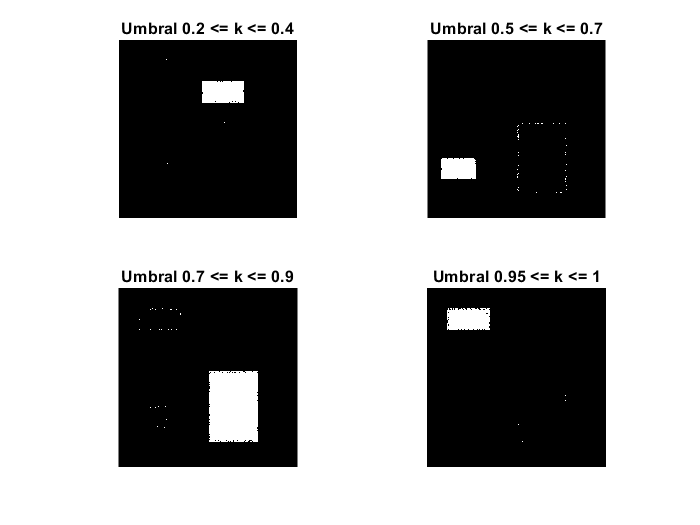

% seleccionando objetos
um5 = (I_wiener >= 0.2) & (I_wiener <= 0.4);
um6 = (I_wiener >= 0.5) & (I_wiener <= 0.7);
um7 = (I_wiener >= 0.7) & (I_wiener <= 0.9);
um8 = (I_wiener >= 0.95) & (I_wiener <= 1);

figure; 
subplot(2,2,1); imshow(um5); title("Umbral 0.2 <= k <= 0.4");
subplot(2,2,2); imshow(um6); title("Umbral 0.5 <= k <= 0.7");
subplot(2,2,3); imshow(um7); title("Umbral 0.7 <= k <= 0.9");
subplot(2,2,4); imshow(um8); title("Umbral 0.95 <= k <= 1");

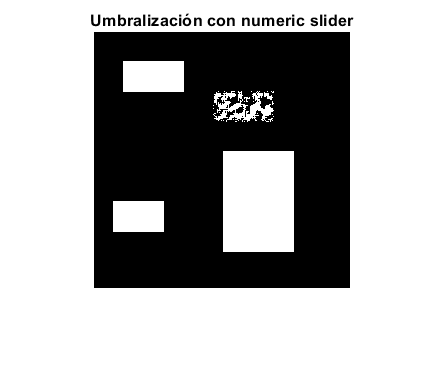

% usando el numeric slider
um_slider = (I_wiener >=0.3);

figure;
imshow(um_slider); title("Umbralización con numeric slider")

- Calcule un nuevo umbral y umbralice la imagen I de forma que se diferencie el fondo de los objetos.

thresh = [0.2 0.7]; % vector de umbrales
I_seg = imquantize(I_wiener, thresh);
I_RGB_seg = label2rgb(I_seg); 

- Muestre cada objeto segmentado con un color diferente con la función `label2rgb`.

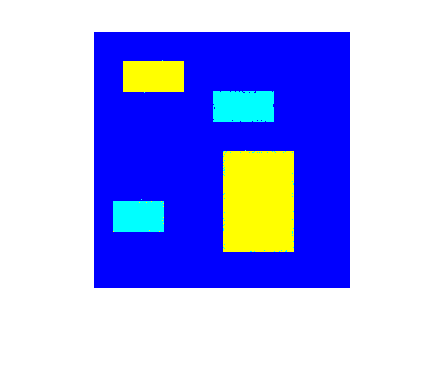

figure;
imshow(I_RGB_seg);

- Cambie el valor de la varianza del ruido (`var_gauss`) y visualice y comente el resultado de la segmentación para distintos valores de la varianza, con y sin filtrado (`wiener2`).

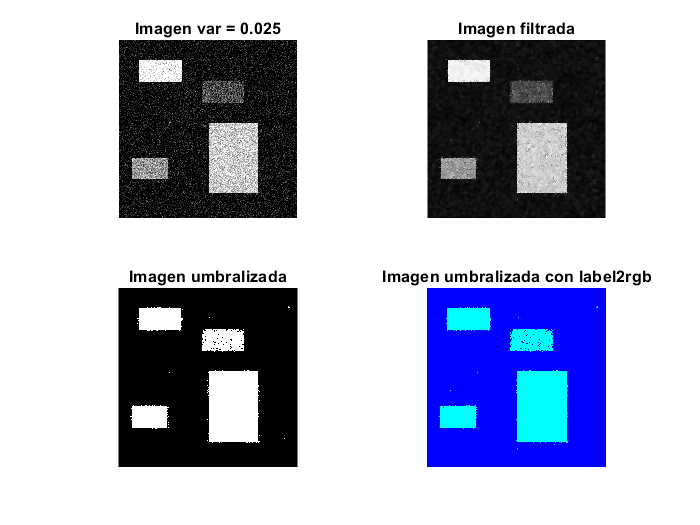

I_gaussian1 = imnoise(I, 'gaussian', 0, 0.025);
I_wiener1 = wiener2(I_gaussian1, [5 5]);
I_wiener1_um = (I_wiener1 >= 0.2);
thresh = [0.2 1]; % vector de umbrales
I_seg1 = imquantize(I_wiener1, thresh);
I_RGB_seg1 = label2rgb(I_seg1); 

figure;
subplot(2,2,1); imshow(I_gaussian1);  title("Imagen var = 0.025");
subplot(2,2,2); imshow(I_wiener1);    title("Imagen filtrada");
subplot(2,2,3); imshow(I_wiener1_um); title("Imagen umbralizada");
subplot(2,2,4); imshow(I_RGB_seg1);   title("Imagen umbralizada con label2rgb");

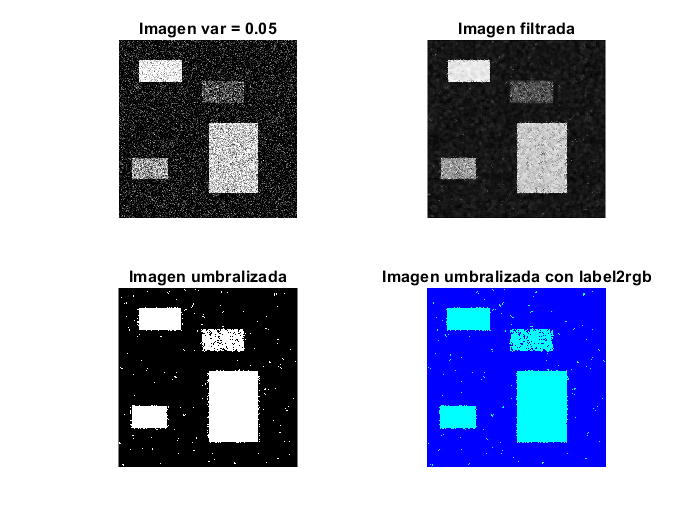

I_gaussian2 = imnoise(I, 'gaussian', 0, 0.05);
I_wiener2 = wiener2(I_gaussian2, [5 5]);
I_wiener2_um = (I_wiener2 >= 0.2);
thresh = [0.2 1]; % vector de umbrales
I_seg2 = imquantize(I_wiener2, thresh);
I_RGB_seg2 = label2rgb(I_seg2); 

figure;
subplot(2,2,1); imshow(I_gaussian2);  title("Imagen var = 0.05");
subplot(2,2,2); imshow(I_wiener2);    title("Imagen filtrada");
subplot(2,2,3); imshow(I_wiener2_um); title("Imagen umbralizada");
subplot(2,2,4); imshow(I_RGB_seg2);   title("Imagen umbralizada con label2rgb");

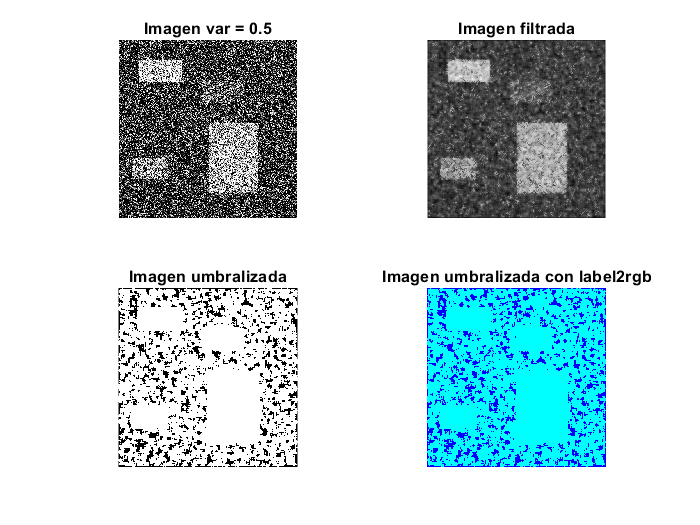

I_gaussian3 = imnoise(I, 'gaussian', 0, 0.5);
I_wiener3 = wiener2(I_gaussian3, [5 5]);
I_wiener3_um = (I_wiener3 >= 0.2);
thresh = [0.2 1]; % vector de umbrales
I_seg3 = imquantize(I_wiener3, thresh);
I_RGB_seg3 = label2rgb(I_seg3); 

figure;
subplot(2,2,1); imshow(I_gaussian3);  title("Imagen var = 0.5");
subplot(2,2,2); imshow(I_wiener3);    title("Imagen filtrada");
subplot(2,2,3); imshow(I_wiener3_um); title("Imagen umbralizada");
subplot(2,2,4); imshow(I_RGB_seg3);   title("Imagen umbralizada con label2rgb");

- Compruebe la segmentación con otras imágenes de Matlab.

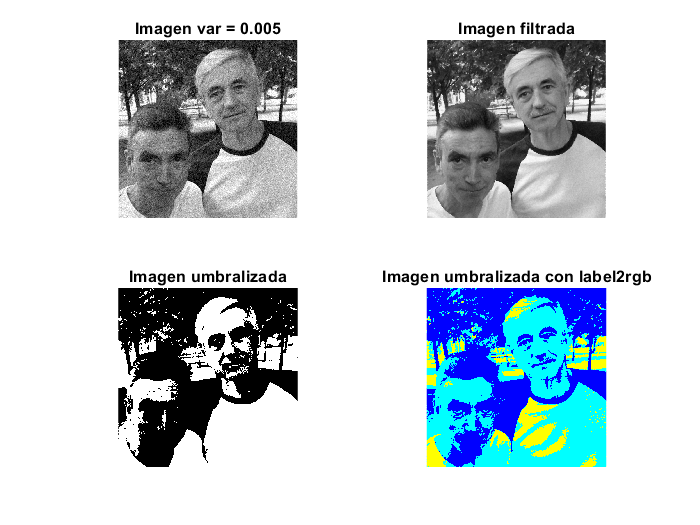

IM1 = imread("javi y miguel viejos.jpg");
IM1_gray = rgb2gray(IM1);
IM1_double = im2double(IM1_gray);

IM1_gaussian = imnoise(IM1_double, 'gaussian', 0, 0.005);
IM1_wiener = wiener2(IM1_gaussian, [5 5]);
IM1_wiener_um = (IM1_wiener >= 0.5);
thresh1 = [0.4 0.8]; 
IM1_seg = imquantize(IM1_wiener, thresh1);
IM1_RGB_seg = label2rgb(IM1_seg); 

figure;
subplot(2,2,1); imshow(IM1_gaussian);  title("Imagen var = 0.005");
subplot(2,2,2); imshow(IM1_wiener);    title("Imagen filtrada");
subplot(2,2,3); imshow(IM1_wiener_um); title("Imagen umbralizada");
subplot(2,2,4); imshow(IM1_RGB_seg);   title("Imagen umbralizada con label2rgb");

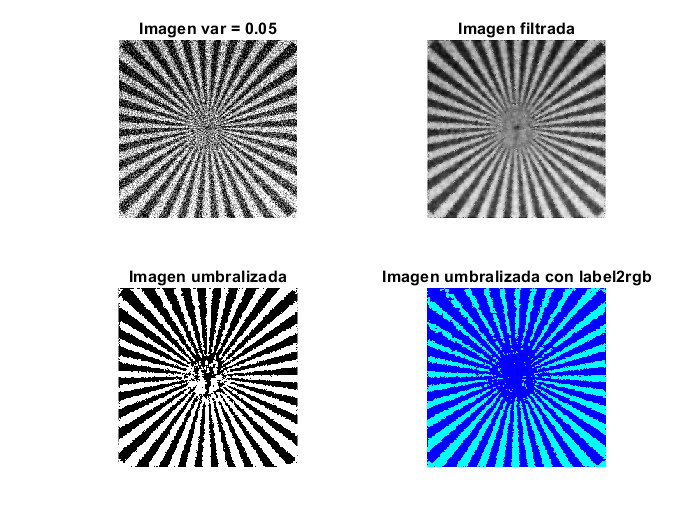

IM2= imread("testpat1.tif");
IM2_double = im2double(IM2);

IM2_gaussian = imnoise(IM2_double, 'gaussian', 0, 0.05);
IM2_wiener = wiener2(IM2_gaussian, [5 5]);
IM2_wiener_um = (IM2_wiener >= 0.5);
thresh2 = [0.6 1]; 
IM2_seg = imquantize(IM2_wiener, thresh2);
IM2_RGB_seg = label2rgb(IM2_seg); 

figure;
subplot(2,2,1); imshow(IM2_gaussian);  title("Imagen var = 0.05");
subplot(2,2,2); imshow(IM2_wiener);    title("Imagen filtrada");
subplot(2,2,3); imshow(IM2_wiener_um); title("Imagen umbralizada");
subplot(2,2,4); imshow(IM2_RGB_seg);   title("Imagen umbralizada con label2rgb");

**2.** Segmentación no supervisada lineal:

- Modifique el apartado anterior para el caso de **2 clases **de modo que **umbralice con la función *****im2bw***, utilizando un umbral global calculado previamente con función ***graythresh*** de Matlab (método no supervisado: no requiere la observación del usuario del histograma, ni la elección de umbrales a partir del mismo): 

                    *   La función *graythresh *utiliza el método Otsu para escoger el umbral global de segmentación, minimizando la varianza dentro de los elementos de las clases y maximizándola entre clases.

                    *  La función *im2bw *umbraliza cualquier imagen de entrada, sea del tipo que sea (incluso imágenes en color), convirtiéndola a imagen de intensidad y “binarizando” esta última con un umbral en un rango entre [0 1]. 

                         level = graythresh(I);

                         BW = im2bw(I,level);

                         figure, imshow(BW)

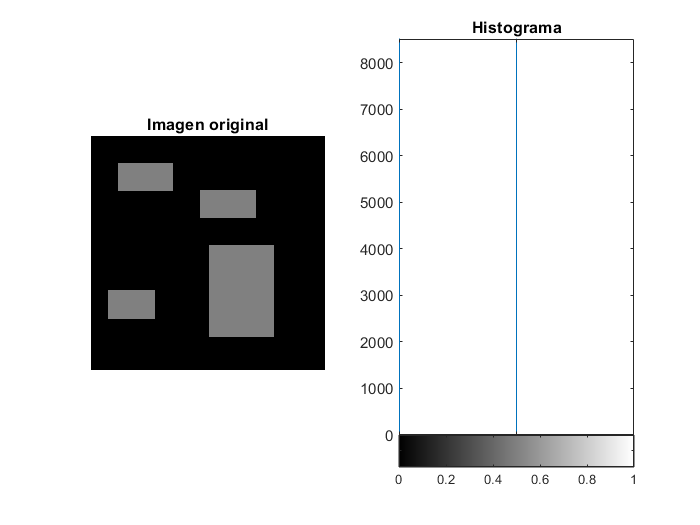

% creamos una imagen en negro
J = zeros(256, 256); 
% creamos cuatro rectángulos
J(60:90, 120:180) = 0.5; 
J(170:200, 20:70) = 0.5; 
J(120:220, 130:200) = 0.5; 
J(30:60, 30:90) = 0.5; 

figure;
subplot(1,2,1); imshow(J); title('Imagen original');
subplot(1,2,2); imhist(J); title('Histograma');

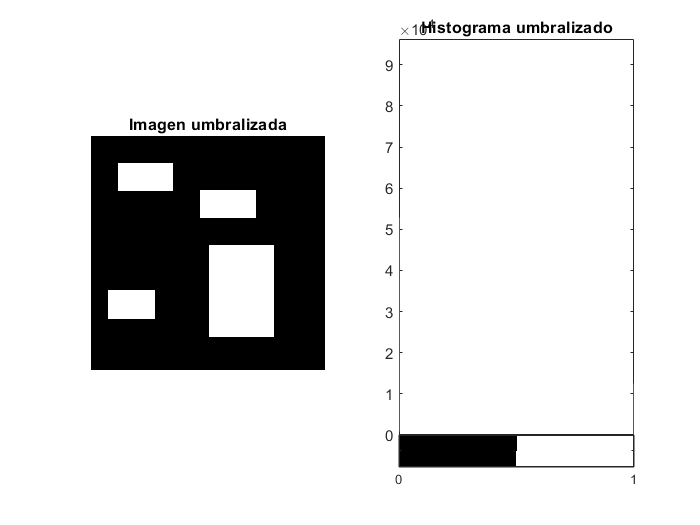

level = graythresh(J);
J_BW = im2bw(J, level);

figure;
subplot(1,2,1); imshow(J_BW); title('Imagen umbralizada');
subplot(1,2,2); imhist(J_BW); title('Histograma umbralizado');

- Pruebe con la imagen 'rice.tif' y otras imágenes de Matlab con histogramas de distintas formas ¿*graythresh* consigue segmentar adecuadamente la imagen en todos los casos? En caso negativo ¿en qué tipo de imágenes suele funcionar bien?

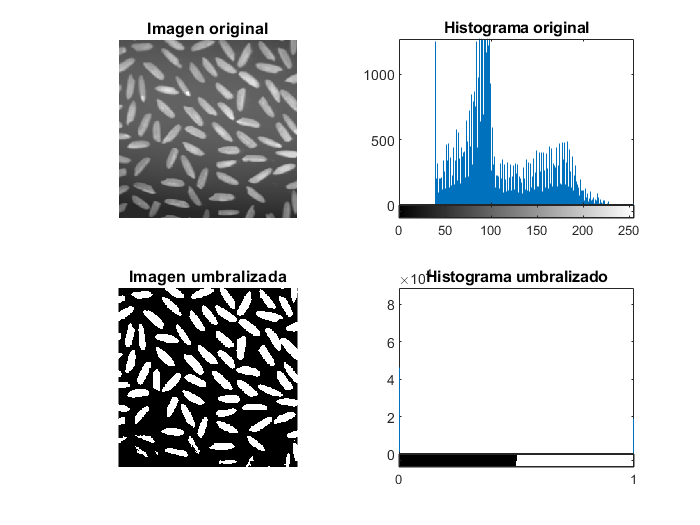

J_rice = imread('rice.tif');
level = graythresh(J_rice);
J_rice_BW = im2bw(J_rice, level);

figure;
subplot(2,2,1); imshow(J_rice); title('Imagen original');
subplot(2,2,2); imhist(J_rice); title('Histograma original');
subplot(2,2,3); imshow(J_rice_BW); title('Imagen umbralizada');
subplot(2,2,4); imhist(J_rice_BW); title('Histograma umbralizado');

**Como se puede observar en la imagen resultante, la función *****graythresh***** no consigue segmentar los granos de arroz de una forma correcta. Esto se debe a que ni el fondo ni los granos de arroz tiene un color uniforme: en el fondo hay varios niveles de gris que se pueden confundir en zonas más oscuras o más claras con el arroz. **

**Este método funcionaría mejor en imágenes con un histograma que tenga unos lóbulos más separados o que no tengan muchos tonos de gris diferentes, como la imagen usada en el apartado anterior (fondo negro y cuadrados grises), donde se segmentan perfectamente los distintos elementos de la imagen.**

**3. **Compare los dos apartados anteriores: segmentación supervisada frente a no supervisada, comentando ventajas e inconvenientes de cada una.

**Segmentación supervisada:**

**    Ventajas:**

- **Es un método más simple y rápido.**

- **Hay funciones en las cuales puedes incorporar más de un umbral usando un vector de umbrales.**

**    Inconvenientes:**

- **Requiere de una supervisión humana tanto de las entradas como de las salidas.**

- **Se debe ir comprobando cual es el umbral adecuado realizando distintas pruebas con valores distintos que debemos introducir. **

**Segmentación no supervisada:**

**    Ventajas:**

- **El sistema aprende y genera un umbral en base a la imagen que pasemos de entrada.**

- **No requiere de supervisión humana, por lo que no tenemos que ir introduciendo valores para el umbral, ya que se genera automáticamente.**

**    Inconvenientes:**

- **Este método (*****graythresh*****) escoge un solo umbral global, por lo que la segmentación no siempre es precisa.**

- **Si la imagen no está limpia (ruido, muchos tonos diferentes...) el umbral generado puede que no se ajuste al resultado que se espera.**

**En conclusión, en función del tipo de imagen que se desee segmentar se debe elegir el tipo de segmentación que se ajuste más a las características de la imagen de entrada.**

**4. **Realice un programa que segmente objetos mediante bordes siguiendo los siguientes pasos:

- Abra la imagen (rice.tif, coins.png, etc...). Para poder probar con distintas imágenes cómodamente, prepare el código para que pueda abrir imágenes con distintos formatos y las convierta a niveles de gris.

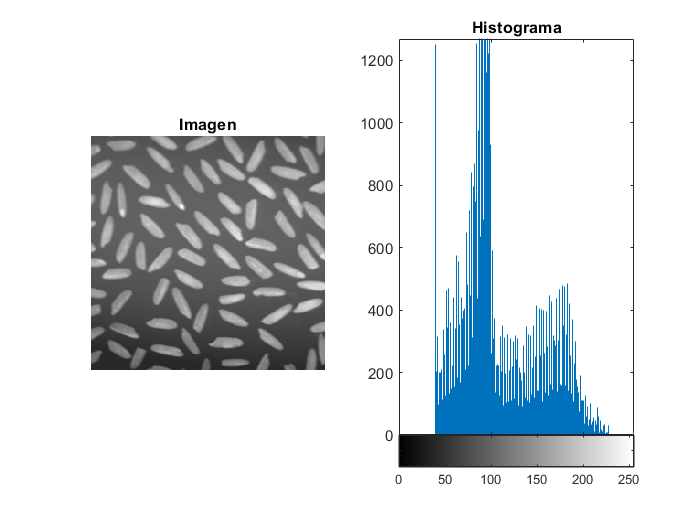

filename = 'rice.tif';
info = imfinfo(filename);
if strcmp(info.ColorType, 'indexed')
    [X, map] = imread(filename);
    K = ind2gray(X, map);
elseif strcmp(info.ColorType, 'truecolor')
    rgb = imread(filename);
    K = rgb2gray(rgb);
else
    K = imread(filename);
end

figure;
subplot(1,2,1); imshow(K); title('Imagen');
subplot(1,2,2); imhist(K); title('Histograma');

         2. Detecte los bordes utilizando el filtro de Canny.

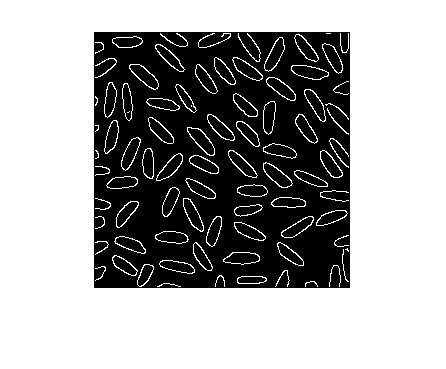

K_canny = edge(K, 'canny');  % imagen binaria de bordes tras filtro de canny 

figure; 
imshow(K_canny);

         3. Cierre contornos dilatando los bordes obtenidos.

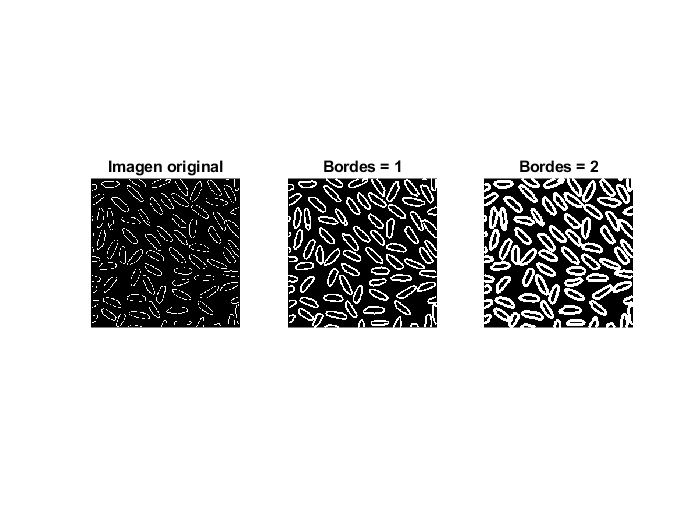

se1 = strel('diamond', 1);
K_canny_dilate1 = imdilate(K_canny, se1);
se2 = strel('diamond', 2);
K_canny_dilate2 = imdilate(K_canny, se2);

figure;
subplot(1,3,1); imshow(K_canny);         title('Imagen original');
subplot(1,3,2); imshow(K_canny_dilate1); title('Bordes = 1');
subplot(1,3,3); imshow(K_canny_dilate2); title('Bordes = 2');

         4. Rellene los contornos obtenidos.

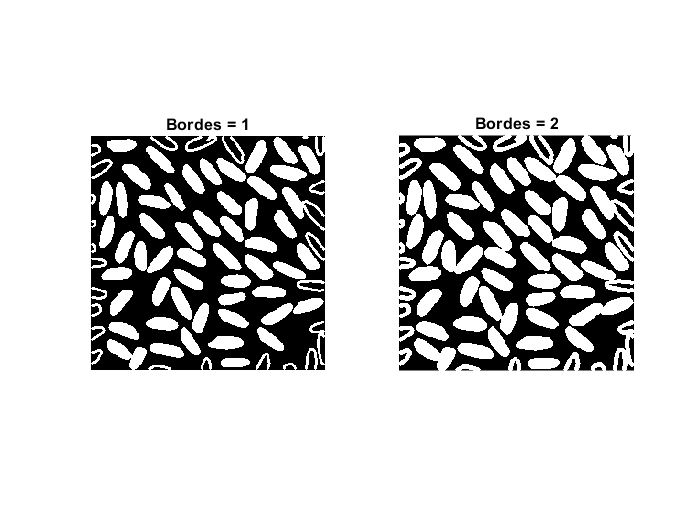

K_fill1 = imfill(K_canny_dilate1, 'holes');
K_fill2 = imfill(K_canny_dilate2, 'holes');

figure;
subplot(1,2,1); imshow(K_fill1); title('Bordes = 1');
subplot(1,2,2); imshow(K_fill2); title('Bordes = 2');

**Para poder rellenar los bordes detectados hemos usado la función *****imfill*****, que rellena los agujeros de la imagen de entrada. Como se puede observar en la imagen resultante, los granos de arroz del centro (los que tienen un borde completo) los ha rellenado perfectamente, pero los granos de arroz de los bordes de la imagen al no tener un borde cerrado y definido que se pueda diferencia del fondo no se rellenan.**

         5. Segmente los distintos objetos, etiquetándolos con *bwlabel.*

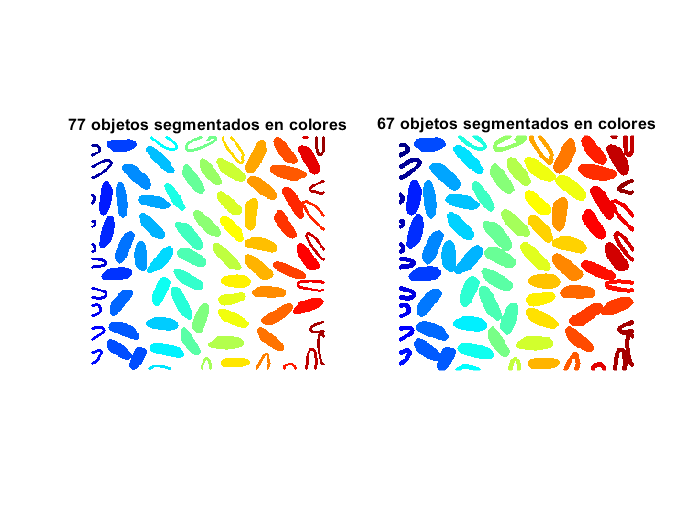

% bordes = 1
K_seg1 = bwlabel(K_fill1); % imagen etiquetada, con un identificador diferente para cada objeto
n_obj1 = max(max(K_seg1)); % número de objetos 
K_RGB1 = label2rgb(K_seg1);
% bordes = 2
K_seg2 = bwlabel(K_fill2); % imagen etiquetada, con un identificador diferente para cada objeto
n_obj2 = max(max(K_seg2)); % número de objetos 
K_RGB2 = label2rgb(K_seg2);

figure;
subplot(1,2,1); imshow(K_RGB1); title(sprintf('%d objetos segmentados en colores', n_obj1));
subplot(1,2,2); imshow(K_RGB2); title(sprintf('%d objetos segmentados en colores', n_obj2));

**Además, hemos realizado una comparativa entre dos grosores de borde diferentes:**

**Dependiendo del grosor que utilicemos, algunos elementos, que inicialmente eran independientes, se unen por algún borde, por lo que los contabiliza como un único objeto. Por este motivo, se puede observar en la imagen en la que mayor grosor tienen los bordes que aparecen menos objetos segmentados, mientras que si usamos un grosor menor, se contabilizan más objetos.**

         6. Cree una máscara solapada con la imagen original utilizando la función `labeloverlay` y muestre la imagen resultante.

t1 = graythresh(K); 
K_BW1 = imbinarize(K_seg1, t1);
t2 = graythresh(K); 
K_BW2 = imbinarize(K_seg2, t2);

figure;
subplot(1,2,1); imshow(K_BW1); title('Bordes = 1');
subplot(1,2,2); imshow(K_BW2); title('Bordes = 2');

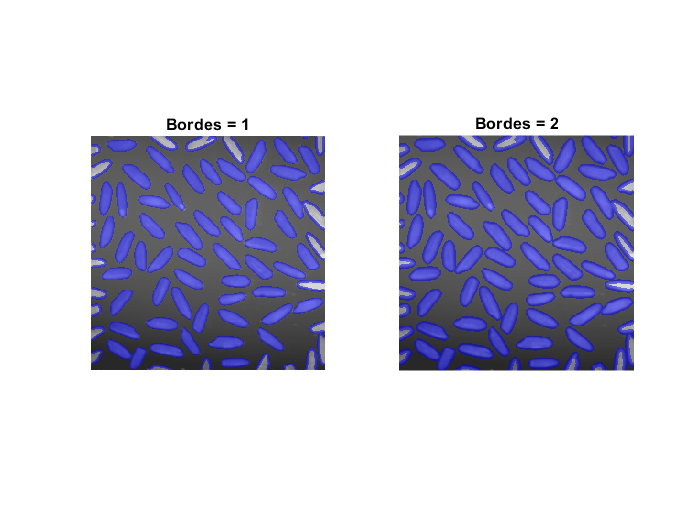

K_masc1 = labeloverlay(K, K_BW1); 
K_masc2 = labeloverlay(K, K_BW2); 

figure;
subplot(1,2,1); imshow(K_masc1); title('Bordes = 1');
subplot(1,2,2); imshow(K_masc2); title('Bordes = 2');

**5. **Modifique el programa anterior para realizar las siguientes comprobaciones:

- Compare los resultados obtenidos con los operadores de bordes `'sobel' ``y` `'canny'`.

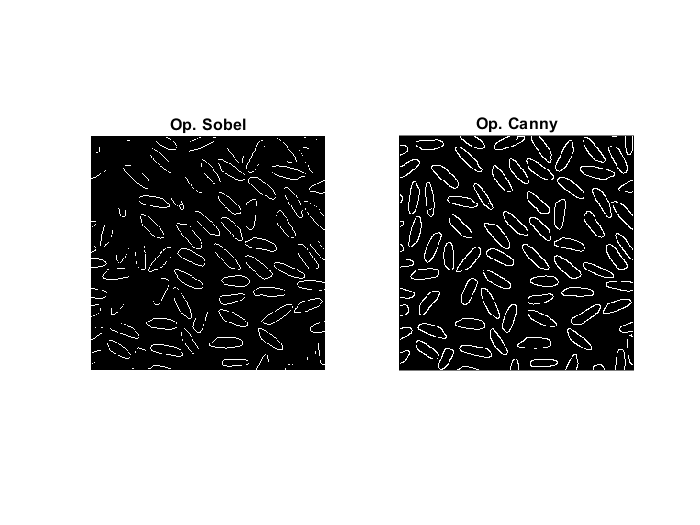

K_sobel = edge(K, 'sobel'); 

figure;
subplot(1,2,1); imshow(K_sobel); title('Op. Sobel');
subplot(1,2,2); imshow(K_canny); title('Op. Canny');

         2. Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación.

         3. Compare los resultados realizando la dilatación (*imdilate*) y eliminando la dilatación del proceso.

         4. Cambie el operador morfológico por `imclose `y compare los resultados.

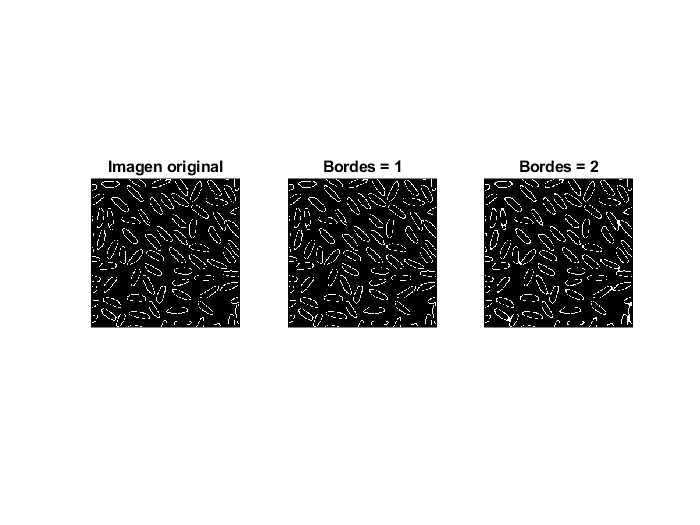

K_canny_close1 = imclose(K_canny, se1); % se1 es inicializado en el ejercicio 4
K_canny_close2 = imclose(K_canny, se2); % se2 es inicializado en el ejercicio 4

figure;
subplot(1,3,1); imshow(K_canny);        title('Imagen original');
subplot(1,3,2); imshow(K_canny_close1); title('Bordes = 1');
subplot(1,3,3); imshow(K_canny_close2); title('Bordes = 2');

**6. **Sobre la imagen 'gantrycrane.png':

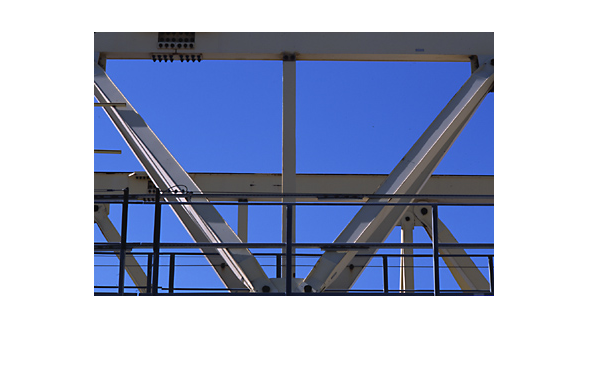

L = imread('gantrycrane.png');

figure;
imshow(L);

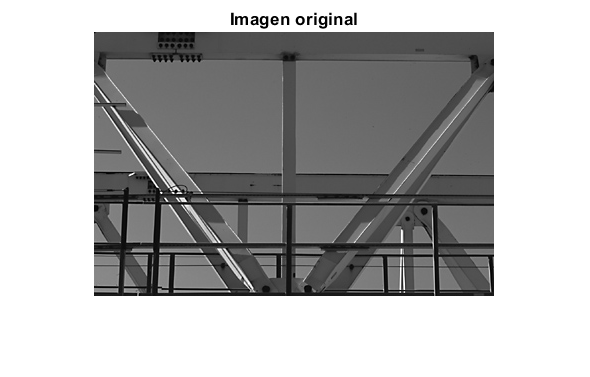

filename = 'gantrycrane.png'; 
info = imfinfo(filename);
if strcmp(info.ColorType, 'indexed')
    [X,map] = imread(filename);
    L = ind2gray(X, map);
elseif strcmp(info.ColorType, 'truecolor')
    rgb = imread(filename);
    L = rgb2gray(rgb);
else
    L = imread(filename);
end

% rotL = imrotate(L, 33, 'crop');

figure;
imshow(L); title('Imagen original');

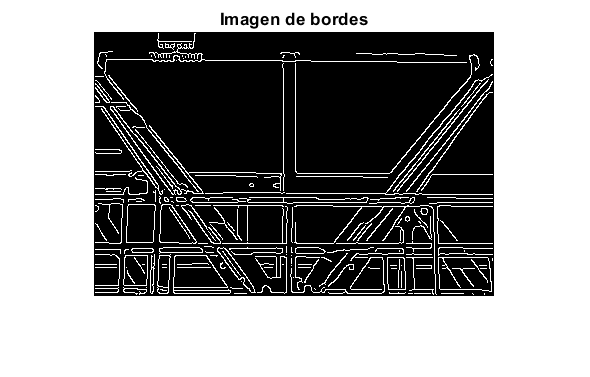

L_canny = edge(L, 'canny');

figure;
imshow(L_canny); title('Imagen de bordes');

- Utilizando la transformada de Hough, pinte las 5 rectas más largas que tengan un ángulo comprendido entre -10º y 10º, con una precisión de 0.5º. 

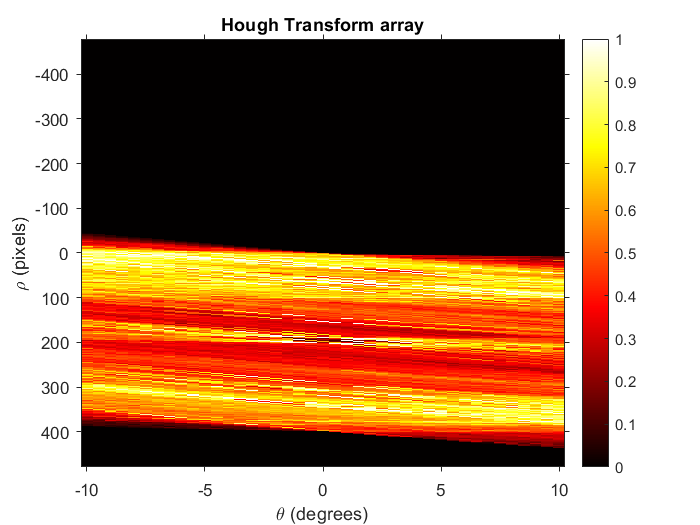

angles = [(-10:0.5:10)];

[H, theta, rho] = hough(L_canny, 'Theta', angles);
% rho = distancia desde el origen a la línea a lo largo de un vector perpendicular
% theta = ángulo entre el eje x y este vector

figure;
imshow(imadjust(rescale(H)), 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit'); 
title('Hough Transform array'); xlabel('\theta (degrees)'); ylabel('\rho (pixels)'); 
axis on, axis normal; colormap(gca, hot); colorbar

th = ceil(0.85*max(H(:))); % umbral de búsqueda
max_peaks = 5; % número máximo de picos a encontrar

P = houghpeaks(H, max_peaks, 'threshold', th, 'Theta', angles)

P =    680    21
   669    22


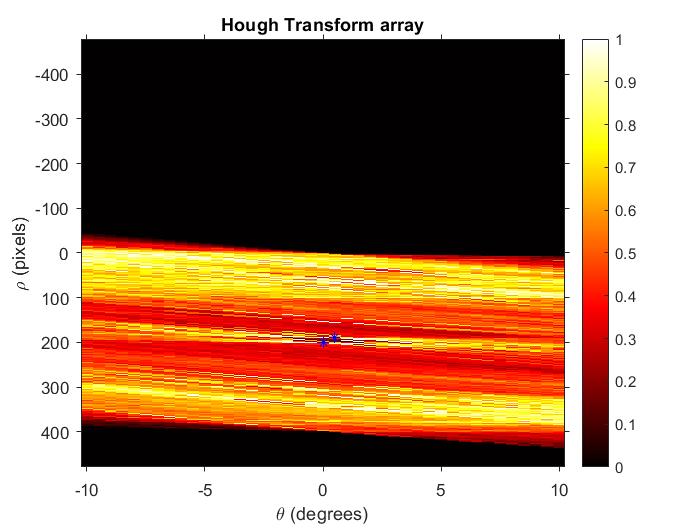

figure;
imshow(imadjust(rescale(H)), 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit'); 
title('Hough Transform array'); xlabel('\theta (degrees)'); ylabel('\rho (pixels)'); 
axis on, axis normal; colormap(gca, hot); colorbar
x = theta(P(:,2)); 
y = rho(P(:,1)); 
hold on;
plot(x, y, '*', 'color', 'blue');
hold off;

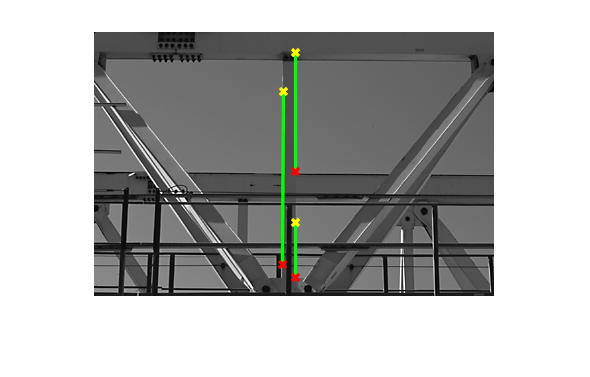

lines = houghlines(L_canny, theta, rho, P, 'FillGap', 10, 'MinLength', 50);

figure;
imshow(L), 
hold on 
max_len = 0;
for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2), 'LineWidth', 2, 'Color', 'green');     
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x', 'LineWidth', 2, 'Color', 'yellow');    
    plot(xy(2,1),xy(2,2),'x', 'LineWidth', 2, 'Color', 'red');      
end 
hold on

**Hemos utilizado la transformada de Hough para encontrar las lineas rectas en la imagen 'gantrycrane.png' entre -10º y 10º con una precisión de 0.5º. Se puede comprobar como obtenemos solo 3 lineas. En la representacion del array de la Transformada de Hough hay dos picos, esos picos corresponden a la localización de las rectas. **

**Como se puede observar, a pesar de aparecer 2 picos en la representación del array, en la imagen de salida donde se muestran las rectas aparecen 3. **

         2. Resalte la recta de mayor longitud pintándola de un color diferente.

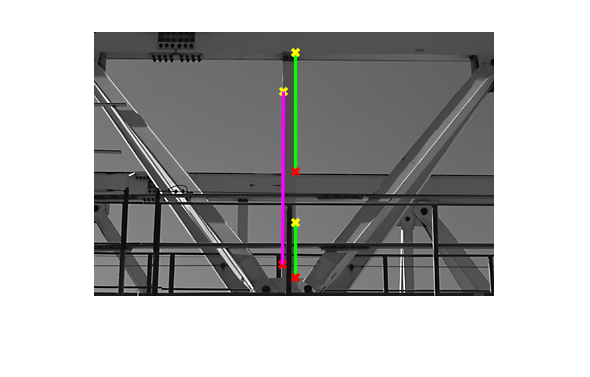

figure;
imshow(L), 
hold on 
max_len = 0;
for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2), 'LineWidth', 2, 'Color', 'green');     
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x', 'LineWidth', 2, 'Color', 'yellow');    
    plot(xy(2,1),xy(2,2),'x', 'LineWidth', 2, 'Color', 'red');      
    len = norm(lines(k).point1 - lines(k).point2);
    if (len > max_len)
        max_len = len;
        xy_long = xy;
    end
end 
plot(xy_long(:,1), xy_long(:,2), 'LineWidth', 2, 'Color', 'magenta');
hold on

         3. Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación.Calcule el número de picos `length(P)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

**7. **Sobre la imagen 'coins.png':

- Utilizando la transformada de Hough localice y pinte el contorno de cada moneda. 

- Resalte la moneda más grande pintándola de un color diferente.

- ¿Cuánto mide la media de los radios de las monedas?

**8.** Transformada Watershed:

- Cargue la imagen `'circles.png'` umbralízela y realize una segmentación utilizando la trasnformación Watershed, tal y como se ha hecho en el ejemplo 1 del fichero VA_Tema3_5_Transf_Watershed.mlx. ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen? 

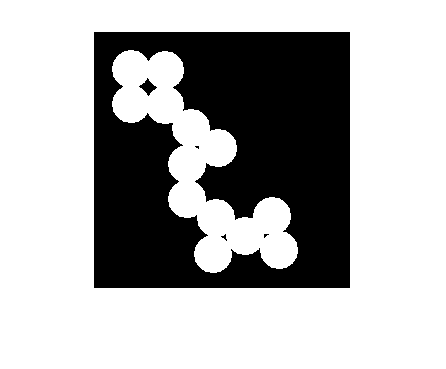

filename = 'circles.png'; 

figure;
imshow(filename);

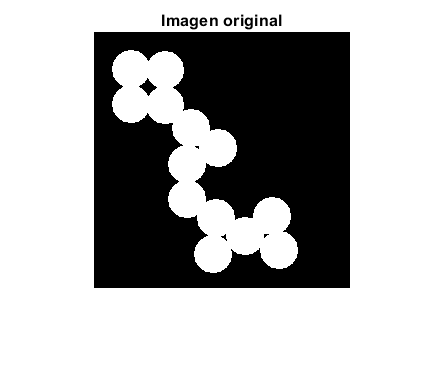

info = imfinfo(filename);
if strcmp(info.ColorType, 'indexed')
    [X,map] = imread(filename);
    N = ind2gray(X, map);
elseif strcmp(info.ColorType, 'truecolor')
    rgb = imread(filename);
    N = rgb2gray(rgb);
else
    N = imread(filename);
end

figure;
imshow(N); title('Imagen original');

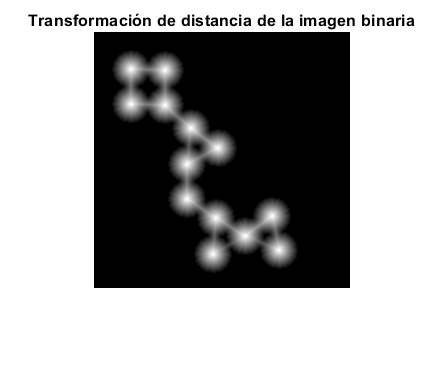

nN = ~N;
N_dist = bwdist(nN);

figure;
imshow(N_dist, []); title('Transformación de distancia de la imagen binaria');

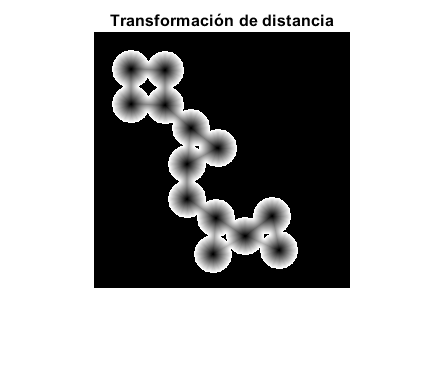

N_dist = -N_dist;
N_dist(nN) = -Inf;

figure;
imshow(N_dist, []); title('Transformación de distancia');

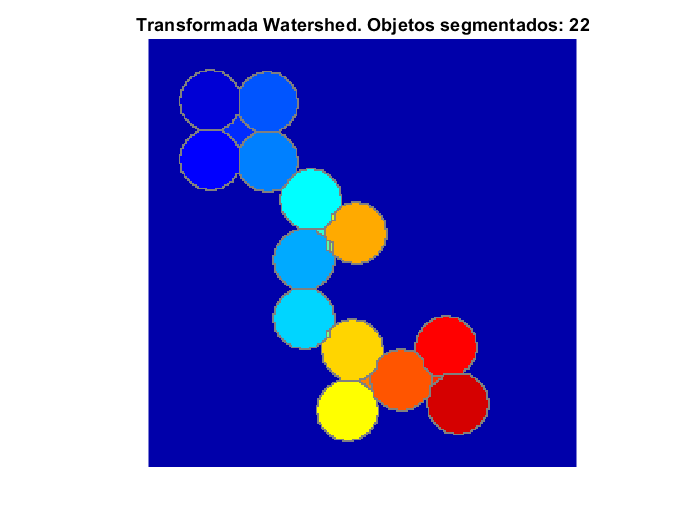

N_watershed = watershed(N_dist);
rgb = label2rgb(N_watershed, 'jet', [.5 .5 .5]);

figure;
imshow(rgb, 'InitialMagnification', 'fit'); title(sprintf('Transformada Watershed. Objetos segmentados: %d', max(max(N_watershed,[],1),[],2)));

         2. Observe el algoritmo el ejemplo 2 del mismo fichero, aplicado a `'rice.png'`  ¿Existe sobre-segmentación, es decir, se han segmentados muchos más objetos de los que hay en la imagen?

         3. Si se ha producido sobre-segmentación con el fichero 'rice.png' realice un rellenado de los objetos segmentados en el apartado anterior con valor 0 añadiendo después de la segmentación por Watershed la instrucción          `BWrellenada=bwfill(L==0,'holes')`) y vuelva a hacer el etiquetado a partir de la imagen `BWrellenada`. Finalmente compruebe si el número de objetos segmentados es menor. 

**Opcional.** Umbralización no lineal:

**9. **Implemente un programa que realice la segmentación supervisada por modelos gaussianos (no lineal) para imágenes de cualquier tamaño y tipo (indexadas, color y en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar, para un número de clases superior a 2. 

**10. **Implemente un programa que realice la segmentación no supervisada por modelos gaussianos (no lineal) para imágenes de cualquier tamaño y tipo (indexadas, color y en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar, para un número de clases superior a 2. 